load sampleEEGdata.mat
data = eeglab2fieldtrip(EEG, 'raw');

cfg = [];
cfg.hpfreq    = 'yes';
cfg.hpfreq      = 1;
cfg.hpfreq  = 'but';
cfg.hpfreq   = 4;
data = ft_preprocessing(cfg, data);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 99 from 99

the call to "ft_preprocessing" took 0 seconds


the input is raw data with 63 channels and 98 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


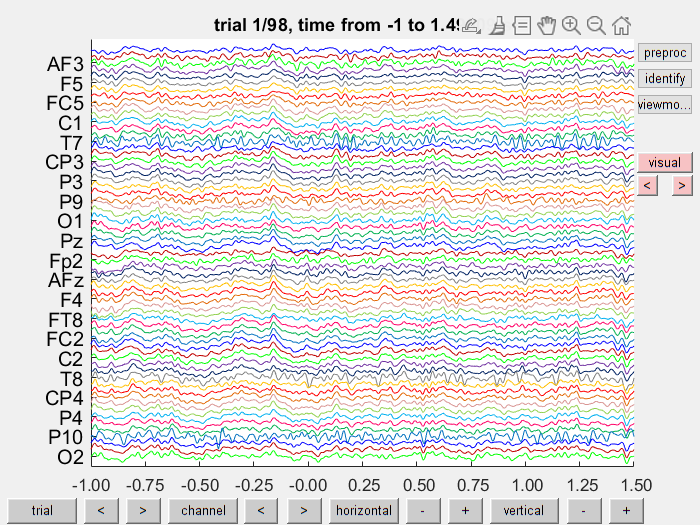

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

cfg = [];
cfg.plotevents = 'yes';
cfg.continuous = 'no';
ft_databrowser(cfg, data_clean)

the input is raw data with 64 channels and 99 trials


detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


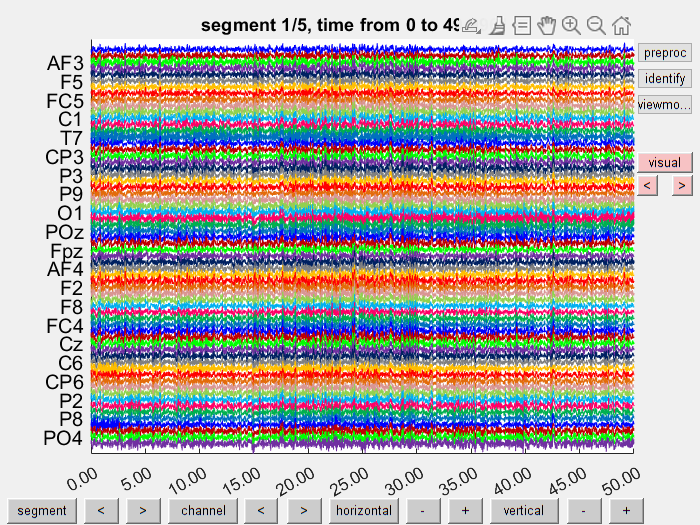

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

cfg = [];
cfg.plotevents = 'yes';
cfg.continuous = 'yes';
cfg.blocksize  = 50;
ft_databrowser(cfg, data)

cfg = [];
cfg.method  = 'trial';
cfg.ylim    = [-50 50];

data_clean = ft_rejectvisual(cfg, data);

the input is raw data with 64 channels and 99 trials
before GUI interaction: 99 trials marked to INCLUDE, 0 trials marked to EXCLUDE
before GUI interaction: 64 channels marked to INCLUDE, 0 channels marked to EXCLUDE
showing the data per trial, all channels at once
the call to "ft_prepare_layout" took 0 seconds
after GUI interaction: 99 trials marked to INCLUDE, 0 trials marked to EXCLUDE
after GUI interaction: 64 channels marked to INCLUDE, 0 channels marked to EXCLUDE
the call to "ft_selectdata" took 0 seconds
the call to "ft_rejectvisual" took 31 seconds


cfg = [];
cfg.method  = 'channel';
cfg.ylim    = [-50 50];

data_clean = ft_rejectvisual(cfg, data);

the input is raw data with 64 channels and 99 trials
before GUI interaction: 99 trials marked to INCLUDE, 0 trials marked to EXCLUDE
before GUI interaction: 64 channels marked to INCLUDE, 0 channels marked to EXCLUDE
showing the data per channel, all trials at once
the call to "ft_prepare_layout" took 0 seconds
after GUI interaction: 99 trials marked to INCLUDE, 0 trials marked to EXCLUDE
after GUI interaction: 64 channels marked to INCLUDE, 0 channels marked to EXCLUDE
the call to "ft_selectdata" took 0 seconds
the call to "ft_rejectvisual" took 20 seconds


cfg = [];
cfg.method  = 'summary';
cfg.ylim    = [-50 50];

data_clean = ft_rejectvisual(cfg, data);

the input is raw data with 64 channels and 99 trials
before GUI interaction: 99 trials marked to INCLUDE, 0 trials marked to EXCLUDE
before GUI interaction: 64 channels marked to INCLUDE, 0 channels marked to EXCLUDE
showing a summary of the data for all channels and trials
computing var [-----------------------------------------------------------/]
after GUI interaction: 98 trials marked to INCLUDE, 1 trials marked to EXCLUDE
after GUI interaction: 63 channels marked to INCLUDE, 1 channels marked to EXCLUDE
the following channels were removed: Iz
the following trials were removed: 63
the call to "ft_selectdata" took 0 seconds
the call to "ft_rejectvisual" took 8 seconds


cfg = [];
cfg.method = 'mtmfft';
cfg.output = 'pow';
cfg.taper = 'hanning';
cfg.foilim = [1 100];
cfg.keeptrials = 'no';

freq = ft_freqanalysis(cfg, data);

the input is raw data with 64 channels and 99 trials
the call to "ft_selectdata" took 0 seconds
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 99/99 nfft: 640 samples, datalength: 640 samples, 1 tapers

the call to "ft_freqanalysis" took 1 seconds


cfg = [];
cfg.method = 'fastica'; 

comp = ft_componentanalysis(cfg, data_clean);

the input is raw data with 63 channels and 98 trials
the call to "ft_selectdata" took 0 seconds
baseline correcting data 
scaling data with 1 over 38.274316
concatenating data
concatenating trials...
Concatenating trial 98 from 98

concatenated data matrix size 63x62720
starting decomposition using fastica
Number of signals: 63
Number of samples: 62720
Calculating covariance...
Dimension reduced to 62 due to the singularity of covariance matrix
Selected [ 62 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 2.08593e-06 ]
Largest remaining (non-zero) eigenvalue [ 0.975825 ]
Sum of removed eigenvalues [ 1.68993e-16 ]
[ 100 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 5.50082e-12 ].
Used approach [ defl ].
Used nonlinearity [ pow3 ].
Starting ICA calculation...
IC 1 ..............computed ( 14 steps ) 
IC 2 ...........................computed ( 27 steps ) 
IC 3 .......computed ( 7 steps ) 
IC 4 ................computed ( 16 steps

the call to "ft_componentanalysis" took 15 seconds


cfg = [];
cfg.elec = data.elec;
lay = ft_prepare_layout(cfg);

creating layout from cfg.elec
creating layout for eeg1010 system


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_prepare_layout" took 0 seconds
the input is component data with 62 components and 63 original channels
the input is raw data with 62 channels and 98 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


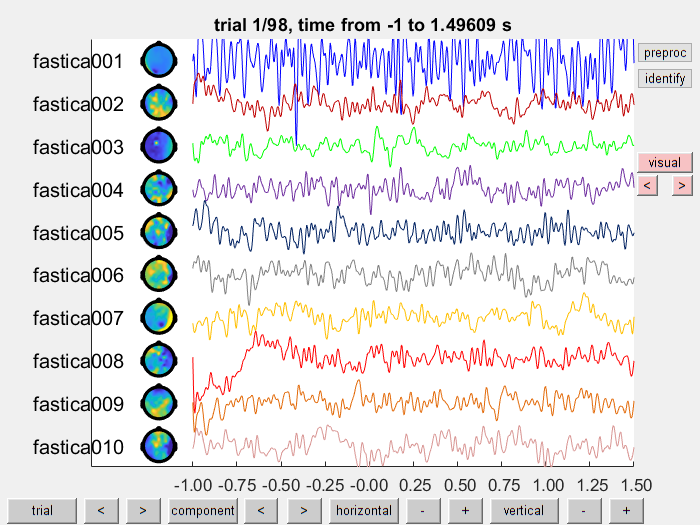

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

cfg = [];
cfg.layout    = lay;
cfg.viewmode  = 'component';
comp.dimord = 'chan_time';
ft_databrowser(cfg, comp);

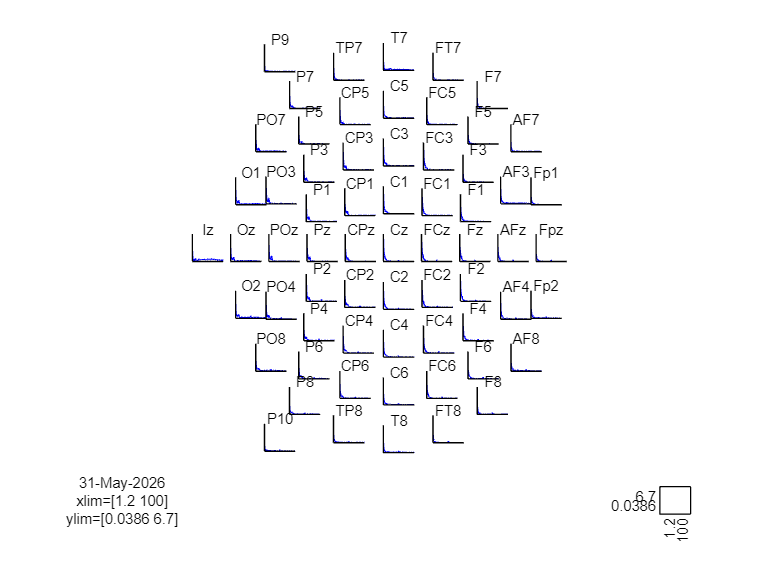

the call to "ft_selectdata" took 0 seconds
creating layout from data.elec
creating layout for eeg1010 system


the call to "ft_prepare_layout" took 0 seconds
the call to "ft_multiplotER" took 2 seconds


cfg = [];
cfg.showlabels = 'yes';
cfg.viewmode   = 'topographic'; %'butterfly'
figure;
ft_multiplotER(cfg, freq);

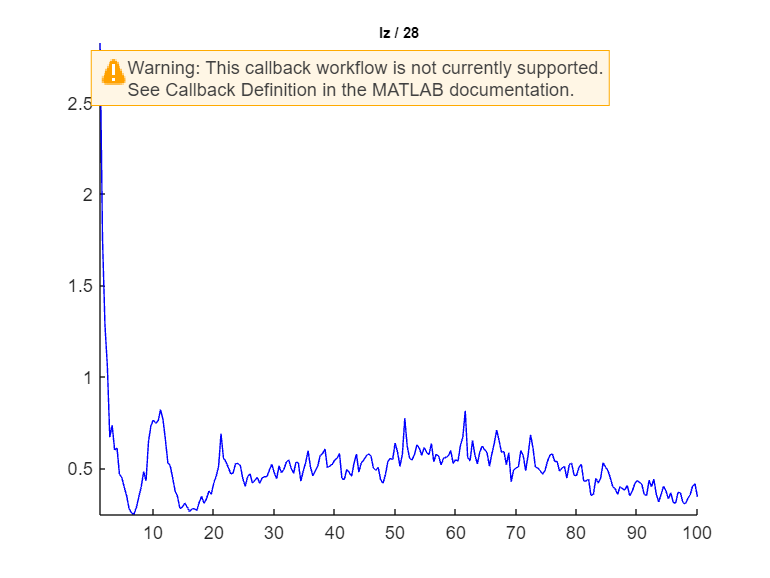

the call to "ft_selectdata" took 0 seconds
the call to "ft_singleplotER" took 0 seconds


cfg = [];
cfg.channel = 'Iz';
cfg.figure  = 'yes';
figure;
ft_singleplotER(cfg, freq);

cfg = [];
cfg.bpfilter    = 'yes';
cfg.bpfreq      = [1 40]; 
cfg.bpfilttype  = 'but';
cfg.bpfiltord   = 4;
data = ft_preprocessing(cfg, data);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 99 from 99

the call to "ft_preprocessing" took 1 seconds
